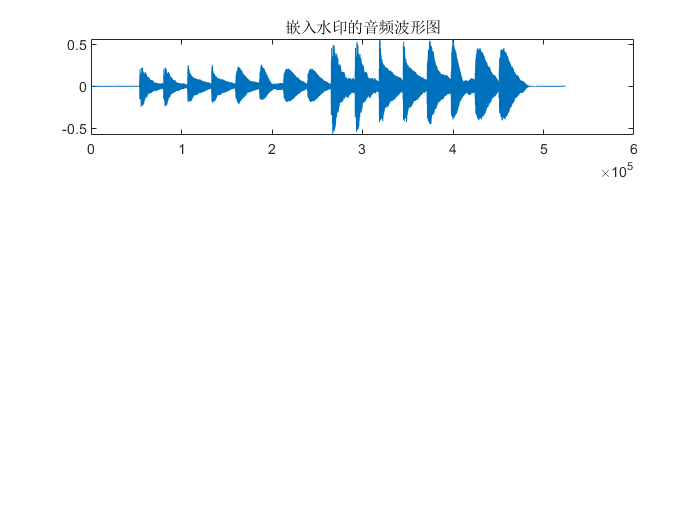

clear all
[a,fs]=audioread('piano.wav');
a = a(:,1); %双通道变单通道
subplot(3,1,1);plot(a);
title('嵌入水印的音频波形图')

w_source='ereettrrt';
originalwatermark=w_source

originalwatermark = 'ereettrrt'

[c,l]=wavedec(a,3,'haar');
ca3=appcoef(c,l,3,'haar');
q=abs(min(ca3));
ave=zeros(1,1024);
size(ca3)

ans =        65532           1


temp3=length(ca3);
for i=1:1024
temp1=mod(i*20,temp3);
temp2=mod((i+1)*20,temp3);
ave(i)=sum(ca3(temp1:temp2))/20;
w1(i)=(mod(fix(ave(i)/q+1/2),2));
end
w=reshape(w1,32,32)

w =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0 


%txtwrite(w,'p2.jpg','jpg');